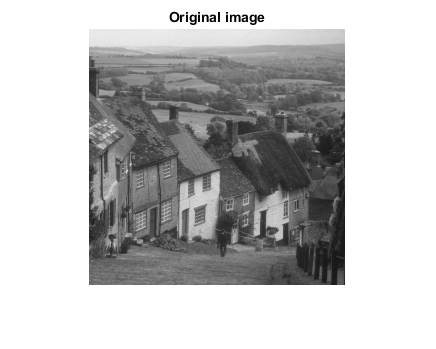

clearvars;
close all;
clc;
% read image files
I = imread('images/57.tif');
imshow(I), title('Original image');

% extract and display bitplanes
figure
Ib = bitget(I,1);
subplot(1,1,1), imshow(Ib,[]), title(strcat('bitplane ', num2str(1)));

 
   sum=0;
   c=0;
   stop=0;
   for i=256:-1:1
       
       for j=256:-1:1
           
           bval=Ib(j,i);
               if(c<8)
                   % sum value holds to binary to decimal as 8 bit data
                     sum= sum + bval*(2^(7-c)) ;
                     c=c+1;
               end
               if(c==8 &&stop==0)
                   
                   fprintf("%c",(sum));
                   if(char(sum)=='#')
                       stop=1;
                       break;
                   end
                   sum=0;
                   c=0;
               end
               
            
       end
     
   end

No programming language is perfect. There is not even a single best language; there are only languages well suited or perhaps poorly suited for particular purposes. Understanding the problem and associated programming requirements is necessary for choosing the language best suited for the solution.#